# BDF-Verfahren

Wir betrachten das (örtlich) diskrete Wärmeleitungsproblem (siehe Buch) mit Ortsschrittweite $h_x:=1/n_x$ für $n_x \in \mathbb{N}$:

   $ y'=Ay, ~~t \in [0,1], ~~y(0)=y^0\in\mathbb{R}^{n_x-1},~~A:= -\frac{1}{h_x^2}tridiag(-1,2,-1) \in \mathbb{R}^{(n_x-1)\times (n_x-1)}
 $.                   (1)

Für die Anfangsbedingung wird $y^0_i=\Phi(i h_x), ~~ i=1,\ldots,n_x-1$, mit $\Phi(x):=\sin(\pi x)$ gewählt.

Die Schrittweite $h_x=1/n_x$ der Ortsdiskretisierung wird gewählt.

nx=20;    hx=1/nx;
A=makeA(nx);
x_i= hx*(1:nx-1)';
ystart= sin(pi*x_i);

In diesem Matlabprogram stehen zur numerischen Lösung dieses Anfangswertproblems folgende Verfahren zur Verfügung (auswählbar mit dem Parameter `choice`):

- BDF2-Verfahren

- BDF3-Verfahren

- Klassisches RK-Verfahren

Es wird ein äquidistantes Gitter mit Schrittweite $h=2^{-k}$, $k=3,\ldots,12$, verwendet. Zur Bestimmung der Startwerte $y^1$ (bei BDF2 und BDF3)  und $y^2$ (nur bei BDF3) kann entweder das implizite Euler-Verfahren  oder die Trapezmethode gewählt werden (auswählbar mit dem Parameter `start`).  Diese Parameter zur Auswahl der Methoden werden gesetzt: 

choice=1; % Methode zur Loesung des AWP
start=1;  % Methode fuer Startwerte (fuer BDF-Methoden)
method= {'BDF2-Verfahren', 'BDF3-Verfahren', 'Klassisches RK-Verfahren'};
method2= {'implizites Euler-Verfahren', 'Trapezmethode'};
fprintf('Methode: %s', method{choice});

Methode: BDF2-Verfahren

if (choice<=2)
    fprintf('Startwerte mit der Methode: %s', method2{start});
end

Startwerte mit der Methode: implizites Euler-Verfahren

Die exakte Lösung des Anfangswertproblems am Endzeitpunkt, $y(1)$, kann mit der Matrixexponentialfunktion (siehe **expm**-Routine in Matlab) bestimmt werden.

Die numerischen Annäherungen $y^j$, $j=1,\ldots,n=2^k$, werden berechnet. Der Fehler am Endzeitpunkt, $\|y^n-y(1)\|_{\infty}$, wird gezeigt. Außerdem wird die Reduktion dieses Fehlers  bei Halbierung der Schrittweite $h$ bestimmt. 

# Aktivität:

Variieren Sie die Parameterwerte** choice** und **start  **und erklären Sie das beobachtete Fehlerverhalten.  Was passiert, wenn man für die Matrix $A$ in (1) eine andere Dimension nimmt, z.B.  $n_x=40$ statt $n_x=20$? Wieso liefert das RK-Verfahren nicht die gewünschten Ergebnisse?

yexakt=expm(A)*ystart;
c=1/start; % Koeffizienten fuer Euler- (c=1) bzw. Trapezmethode (c=1/2)
I=eye(nx-1,nx-1);
fprintf('\nFehler am Endzeitpunkt für h=1/32,...., 1/4096 und Fehlerreduktionsfaktor:\n');


Fehler am Endzeitpunkt für h=1/32,...., 1/4096 und Fehlerreduktionsfaktor:


hh= zeros(1,6);    error= hh;
for k=5:10  
    h=2^(-k); n=2^k;
    yalt=ystart;
    switch choice
        case 1 % BDF2-Verfahren
            % Startwert
            yalt1= (I - c*h*A)\((I + (1-c)*h*A)*yalt); 
            % BDF2
            for j=1:n-1   % Bestimmung der Annaeherung y^(j+1)
                yneu=(3/2*I - h*A)\(2*yalt1 - 0.5*yalt);   
                yalt=yalt1;    yalt1=yneu; % Variablenshift
            end
        case 2 % BDF3-Verfahren
            % Startwerte
            yalt1=(I - c*h*A)\((I + (1-c)*h*A)*yalt);
            yalt2=(I - c*h*A)\((I + (1-c)*h*A)*yalt1); 
            % BDF3
            for j=2:n-1   % Bestimmung der Annaeherung y^(j+1)
                yneu=(11/6*I - h*A)\(3*yalt2 - 3/2*yalt1 + 1/3*yalt);
                yalt=yalt1;    yalt1=yalt2;    yalt2=yneu; % Variablenshift
            end
        case 3  % klassisches RK-Verfahren
            for j=0:n-1   % Bestimmung der Annaeherung y^(j+1)
                k1= A*yalt;
                k2= A*(yalt + 0.5*h*k1);
                k3= A*(yalt + 0.5*h*k2);
                k4= A*(yalt + h*k3);
                yneu= yalt + h/6*(k1 + 2*k2 + 2*k3 + k4);
                yalt= yneu;
            end
    end
    disp('-----------------'); 
    Schrittweite=h
    Fehler=norm(yneu-yexakt,'inf')
    kk= k-4; % index starting with 1
    hh(kk)=h;    error(kk)=Fehler;
    if (kk>1) 
        Fehlerreduktionsfaktor= error(kk-1)/error(kk) 
    end
end

-----------------


Schrittweite = 0.0313

Fehler = 1.5465e-05

-----------------


Schrittweite = 0.0156

Fehler = 3.5352e-06

Fehlerreduktionsfaktor = 4.3745

-----------------


Schrittweite = 0.0078

Fehler = 8.3841e-07

Fehlerreduktionsfaktor = 4.2165

-----------------


Schrittweite = 0.0039

Fehler = 2.0379e-07

Fehlerreduktionsfaktor = 4.1141

-----------------


Schrittweite = 0.0020

Fehler = 5.0215e-08

Fehlerreduktionsfaktor = 4.0584

-----------------


Schrittweite = 9.7656e-04

Fehler = 1.2462e-08

Fehlerreduktionsfaktor = 4.0295

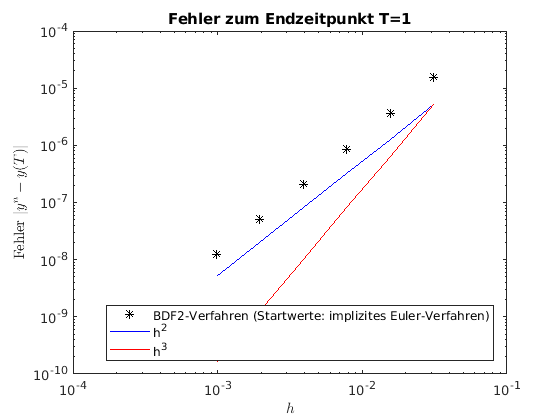

plotError( hh, error, 1, [method{choice} ' (Startwerte: ' method2{start} ')'])

 function A=makeA(n)
     h=1/n;
     A=2*eye(n-1,n-1);
     A=A-diag(ones(n-2,1),1) - diag(ones(n-2,1),-1);
     A=-h^(-2)*A;
 end

function plotError( h, error, T, method) 
% Fehlerplot
clf
loglog(h,error,'k*');
hold on;
scale= error(1)/3;
hs= h(1);
loglog(h,scale*(h/hs).^2,'b-', h,scale*(h/hs).^3,'r-');
title( ['Fehler zum Endzeitpunkt T=',num2str(T)]);
legend(method, 'h^2', 'h^3', 'Location','southeast');
xlabel('$h$','Interpreter','latex'); ylabel('Fehler $|y^n-y(T)|$','Interpreter','latex');
hold off;
end